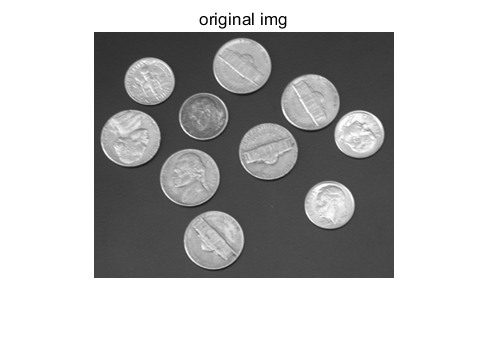

clear; clc;
a = imread('coins.png');
figure; imshow(a); title('original img')

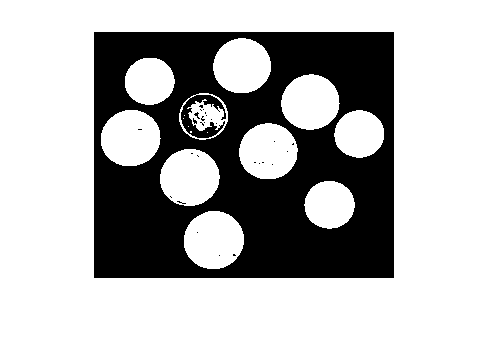


b = im2bw(a);
figure; imshow(b)

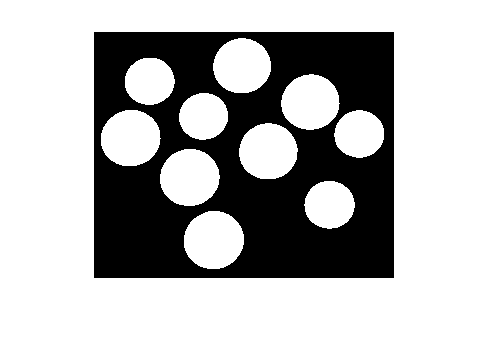


c = imfill(b, 'holes');
figure; imshow(c)

label = bwlabel(c);
max(max(label))

ans = 10

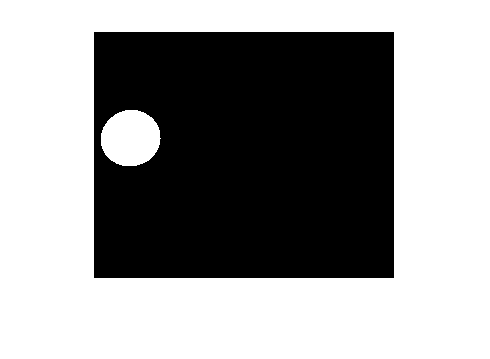

im1 = (label == 1);
figure; imshow(im1)

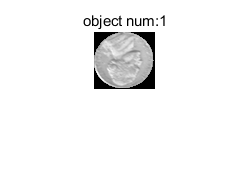

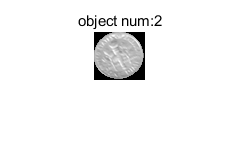

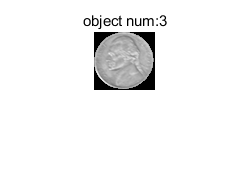

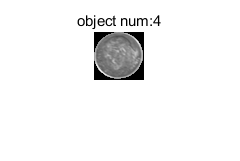

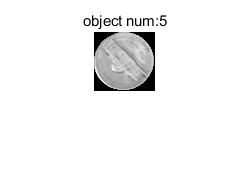

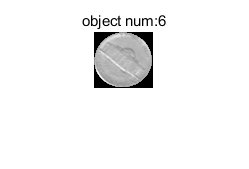

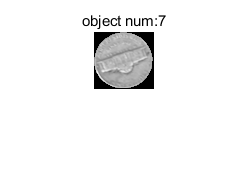

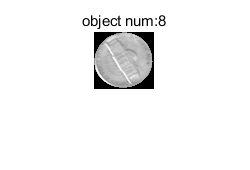

for j = 1:max(max(label))
    [row, col] = find(label == j);
    len = max(row) - min(row) + 2;
    breadth = max(col) - min(col) + 2;
    target = uint8(zeros(len, breadth));
    sx = min(row) - 1;
    sy = min(col) - 1;
    
    for i = 1:size(row, 1)
        x = row(i, 1) - sx;
        y = col(i, 1) - sy;
        target(x, y) = a(row(i, 1), col(i, 1));
    end
    mytitle = strcat('object num: ', num2str(j));
    figure; imshow(target); title(mytitle);
end